%assign 1
%Creating matrix of 7,7 size and allocating all values to 1 and multip
%lying it by 2 afterwawrds creating a diagonal matrix with same dime
%nsions and multiplying that diagonal with to and decrementing it

M = ones(7,7)*2 - eye(7,7)*2

M =      0     2     2     2     2     2     2
     2     0     2     2     2     2     2
     2     2     0     2     2     2     2
     2     2     2     0     2     2     2
     2     2     2     2     0     2     2
     2     2     2     2     2     0     2
     2     2     2     2     2     2     0



%assign 2.
%(A'*A)⁻*A'*b
A = [1 1; 1.5 2];
b = [2;-3];
Sulut = (A'*A)^-1

Sulut =    20.0000  -16.0000
  -16.0000   13.0000


Vastaus = Sulut * A'*b

Vastaus =    14.0000
  -12.0000



%assign  3.
%Creating an fplot that works as an functiongraph where we set (x) as the
%variable
fplot(@(x)3*x^3+2*x^2-3*x-1,"r", "LineStyle", "--", "LineWidth",5)

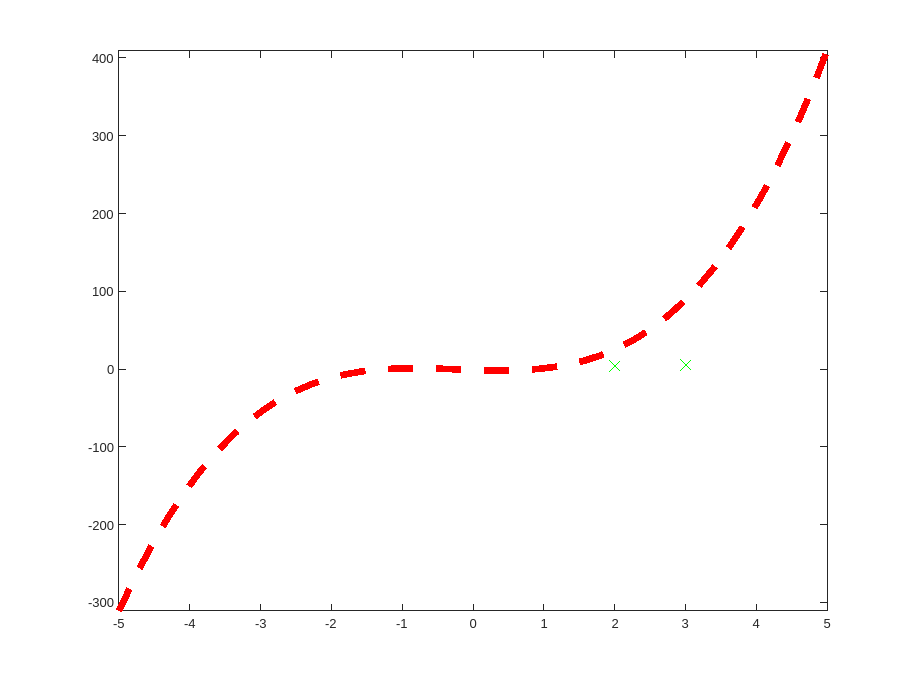

hold on

%assign.4.
%Assigning vectors with x and y values then editing the graphics
%to the graph
x = [2,3,2];
y =[3,4,3];
plot(x,y,"x","MarkerSize",10,"Color","g")


%assign. 5*.
%setting randi ruleset 1  - 9 values only accepted and dimensions of the
%matrice is 1,7 so 1 row and 7 columns appending the last 3 
%randomly generated numbers to create final matrice with 10 random numbers
Lottary = randi([1 9],1,7)

Lottary =      4     4     5     6     9     7     4


Last3 = randi([1 9],1,3)

Last3 =      8     2     1


LottaryFull = cat(2,Lottary,Last3)

LottaryFull =      4     4     5     6     9     7     4     8     2     1



%assign. 6*.
%Implementing matrix 9by7 size and then allocating it with 0 values
%afterwards setting x and y to 1,1 to start off from (1,1) and starting the
%for loop to go through each value in matrix 9*7. Checking for condition
%when y reaches 7 and setting its value to 1 and x value to 1 as the matrix
%size ends at y = 7 
Matrice = zeros(9,7)

Matrice =      0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0


    x = 1;
    y= 1;
for i = 1:9*7
   if y > 7
       x = x+1;
       y = 1;
   end
   Matrice(x,y) = i;
   y = y+1;
end
Matrice

Matrice =      1     2     3     4     5     6     7
     8     9    10    11    12    13    14
    15    16    17    18    19    20    21
    22    23    24    25    26    27    28
    29    30    31    32    33    34    35
    36    37    38    39    40    41    42
    43    44    45    46    47    48    49
    50    51    52    53    54    55    56
    57    58    59    60    61    62    63



%assign. 7
%Same as previous assignment just in the reverse section from 49 to 0
%Each time the loop goes once the value 49 is decreased by 1 until it
%reaches 0 
%after create an eye operator to get the diagonal value and decrement
%From the matrix to create a 0 diag value
Matrice = zeros(7,7);
    x=1;
    y=1;
    val = 49;
for i = 1:7*7
    if y > 7;
        x = x+1;
        y = 1;
    end
Matrice(x,y) = val;
y = y+1;
val = val-1;
end
diagVect = eye(7,7);
Minus = Matrice.*diagVect;
Matrice = Matrice -Minus

Matrice =      0    48    47    46    45    44    43
    42     0    40    39    38    37    36
    35    34     0    32    31    30    29
    28    27    26     0    24    23    22
    21    20    19    18     0    16    15
    14    13    12    11    10     0     8
     7     6     5     4     3     2     0



%assign. 8
%(A^t*A)⁻*A^t*b
%same as  assign 2
b = [10;5;8;1;4;9;8];
A = Matrice;

Val = (A'*A)^-1;
x = Val * A'*b

x =     0.2182
    0.3256
    0.2425
    0.5062
    0.4300
   -0.0041
   -1.3832



%assign 9
%a.) row 4 column 5
val = A(4,5);
%b.) row 3 all values on the row
val = A(3,:);
%c.) all row values on column 4
val = A(:,4);
%d.) all row values on final column
val = A(:,end);

%assign 10*
%a.) replacing row 3 with ones
B = ones(1,7)

B =      1     1     1     1     1     1     1


A(3,:)=B

A =      0    48    47    46    45    44    43
    42     0    40    39    38    37    36
     1     1     1     1     1     1     1
    28    27    26     0    24    23    22
    21    20    19    18     0    16    15
    14    13    12    11    10     0     8
     7     6     5     4     3     2     0


%b.) replacing 6th column values with 4th row values
A(:,6) = A(4,:)

A =      0    48    47    46    45    28    43
    42     0    40    39    38    27    36
     1     1     1     1     1    26     1
    28    27    26     0    24     0    22
    21    20    19    18     0    24    15
    14    13    12    11    10    23     8
     7     6     5     4     3    22     0


%c.) changing 5th and 3th column value positions
B = A(:,5)

B =     45
    38
     1
    24
     0
    10
     3


A(:,5)=A(:,3)

A =      0    48    47    46    47    28    43
    42     0    40    39    40    27    36
     1     1     1     1     1    26     1
    28    27    26     0    26     0    22
    21    20    19    18    19    24    15
    14    13    12    11    12    23     8
     7     6     5     4     5    22     0


A(:,3) = B

A =      0    48    45    46    47    28    43
    42     0    38    39    40    27    36
     1     1     1     1     1    26     1
    28    27    24     0    26     0    22
    21    20     0    18    19    24    15
    14    13    10    11    12    23     8
     7     6     3     4     5    22     0


%d.) added additional column using cat and specifying the direction
%then summing first column and 7th column for last column value
AdditionalColumn =zeros(7,1)

AdditionalColumn =      0
     0
     0
     0
     0
     0
     0


newMatrx = cat(2,A,AdditionalColumn)

newMatrx =      0    48    45    46    47    28    43     0
    42     0    38    39    40    27    36     0
     1     1     1     1     1    26     1     0
    28    27    24     0    26     0    22     0
    21    20     0    18    19    24    15     0
    14    13    10    11    12    23     8     0
     7     6     3     4     5    22     0     0


newMatrx = A

newMatrx =      0    48    45    46    47    28    43
    42     0    38    39    40    27    36
     1     1     1     1     1    26     1
    28    27    24     0    26     0    22
    21    20     0    18    19    24    15
    14    13    10    11    12    23     8
     7     6     3     4     5    22     0


A(:,8)=(A(:,1)+A(:,7))

A =      0    48    45    46    47    28    43    43
    42     0    38    39    40    27    36    78
     1     1     1     1     1    26     1     2
    28    27    24     0    26     0    22    50
    21    20     0    18    19    24    15    36
    14    13    10    11    12    23     8    22
     7     6     3     4     5    22     0     7



%e ???

%f multiplication of columns
F = A(:,2).*A(:,6)

F =         1344
           0
          26
           0
         480
         299
         132



%g,h multiplying values 1 by 1 in for loop previously used same styled
%for loop
x= 1;
for i = 1:7
   A(x,2) * A(x,6)
   x = x+1;
end

ans = 1344

ans = 0

ans = 26

ans = 0

ans = 480

ans = 299

ans = 132


%H incrementing each value one by one in matrix using similar for loop
x = 1;

for i = 1:7
   A(x,5)^3  
   x = x+1;
end

ans = 103823

ans = 64000

ans = 1

ans = 17576

ans = 6859

ans = 1728

ans = 125